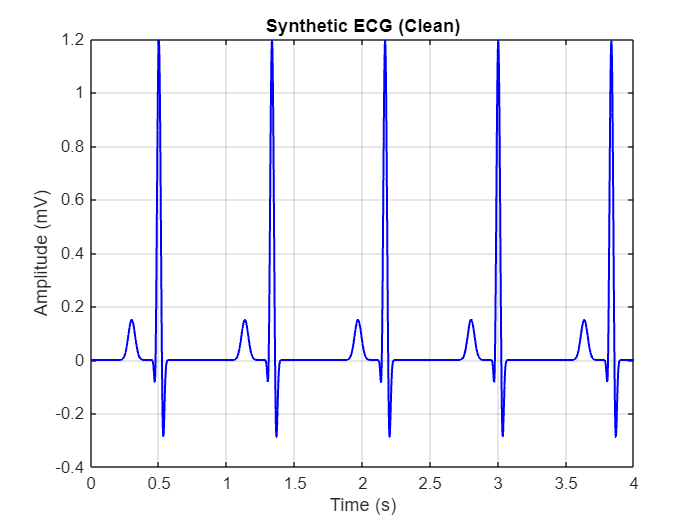

%% Part 1: Generate a clean synthetic ECG signal 
clc; clear; close all; 
fs = 500;              
T  = 10;               
t  = 0:1/fs:T-1/fs;    
% Sampling frequency (Hz) 
% Duration (s) 
% Time vector 
% Build ECG as sum of Gaussian components (P, Q, R, S, T) 
heartRate = 72;                    
% bpm 
RR = 60/heartRate;                 
nBeats = floor(T/RR); 
ecg = zeros(size(t)); 
% seconds between beats 
gauss = @(t,mu,sig,amp) amp*exp(-((t-mu).^2)/(2*sig^2)); 
for k = 1:nBeats 
tc = (k-1)*RR + 0.5;   
% R-peak center 
ecg = ecg + gauss(t, tc-0.20,  0.025,  0.15);   
ecg = ecg + gauss(t, tc-0.025, 0.008, -0.20);   
ecg = ecg + gauss(t, tc,       0.013,  1.20);   
ecg = ecg + gauss(t, tc+0.030, 0.010, -0.35);   
% P wave 
% Q wave 
% R wave 
% S wave  
end 
ecg = ecg + gauss(t, tc+0.200, 0.040,  0.30);   
% T wave 
% Store as the clean ECG 
ecgClean = ecg; 
% Visualize 
figure('Name','Synthetic ECG (Clean)'); 
plot(t, ecgClean, 'b', 'LineWidth', 1.2); 
xlabel('Time (s)'); ylabel('Amplitude (mV)'); 
title('Synthetic ECG (Clean)'); 
xlim([0 4]); grid on; 

%% Part 2: Detect R-peaks using simple thresholding 
threshold = 0.6;                          
aboveThresh = ecgClean > threshold; 
% mV 
% Find transitions from 0 to 1 (rising edges) 
rPeaks = find(diff([0 aboveThresh]) == 1); 
% Remove peaks that are too close (refractory period ~200 ms) 
minDist = round(0.2 * fs); 
keep = true(size(rPeaks)); 
for i = 2:length(rPeaks) 
if rPeaks(i) - rPeaks(i-1) < minDist 
keep(i) = false; 
end 
end 
rPeaks = rPeaks(keep); 
fprintf('Number of R-peaks detected: %d\n', length(rPeaks));

Number of R-peaks detected: 12


%% Part 3: RR intervals and heart rate 
rrSamples = diff(rPeaks); 
rrSeconds = rrSamples / fs; 
meanRR = mean(rrSeconds); 
heartRateEst = 60 / meanRR; 
fprintf('Mean RR interval: %.4f s\n', meanRR); 

Mean RR interval: 0.8333 s


fprintf('Estimated heart rate: %.2f bpm\n', heartRateEst); 

Estimated heart rate: 72.01 bpm


fprintf('Min RR: %.4f s | Max RR: %.4f s\n', min(rrSeconds), max(rrSeconds));

Min RR: 0.8320 s | Max RR: 0.8340 s


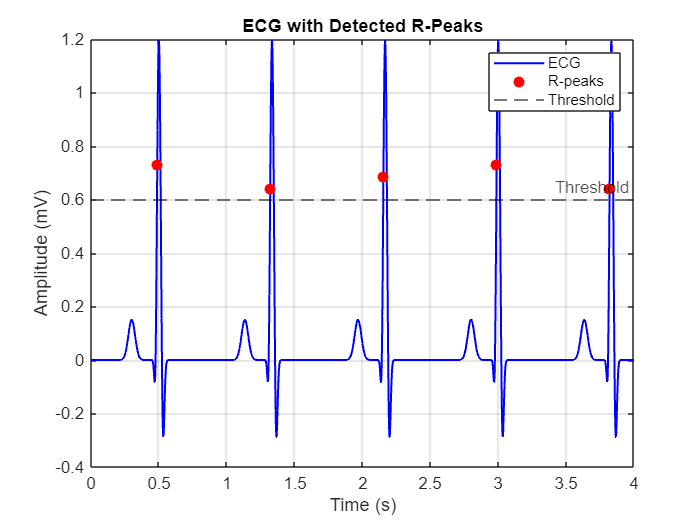

%% Part 4: Plot ECG with detected R-peaks 
figure('Name','R-Peak Detection'); 
plot(t, ecgClean, 'b', 'LineWidth', 1.2); hold on; 
plot(t(rPeaks), ecgClean(rPeaks), 'ro', 'MarkerFaceColor','r', 'MarkerSize', 6); 
yline(threshold, 'k--', 'Threshold'); 
xlabel('Time (s)'); ylabel('Amplitude (mV)'); 
title('ECG with Detected R-Peaks'); 
xlim([0 4]); grid on; 
legend('ECG','R-peaks','Threshold'); 

%% Part 5: Time domain statistics of the ECG 
meanAmp     = mean(ecgClean); 
stdAmp      = std(ecgClean); 
peakToPeak  = max(ecgClean) - min(ecgClean); 
rmsAmp      = rms(ecgClean); 
energySig   = sum(ecgClean.^2) / fs; 
powerSig    = energySig / T; 
fprintf('--- Time Domain Statistics ---\n'); 

--- Time Domain Statistics ---


fprintf('Mean amplitude     : %.4f mV\n', meanAmp);

Mean amplitude     : 0.0459 mV


fprintf('Std deviation   : %.4f mV\n', stdAmp);   

Std deviation   : 0.1911 mV


fprintf('Peak-to-peak : %.4f mV\n', peakToPeak);    

Peak-to-peak : 1.4813 mV


fprintf('RMS amplitude  : %.4f mV\n', rmsAmp);     

RMS amplitude  : 0.1965 mV


fprintf('Signal energy   : %.4f mV^2·s\n', energySig);   

Signal energy   : 0.3861 mV^2·s


fprintf('Average power : %.4f mV^2\n', powerSig);      

Average power : 0.0386 mV^2


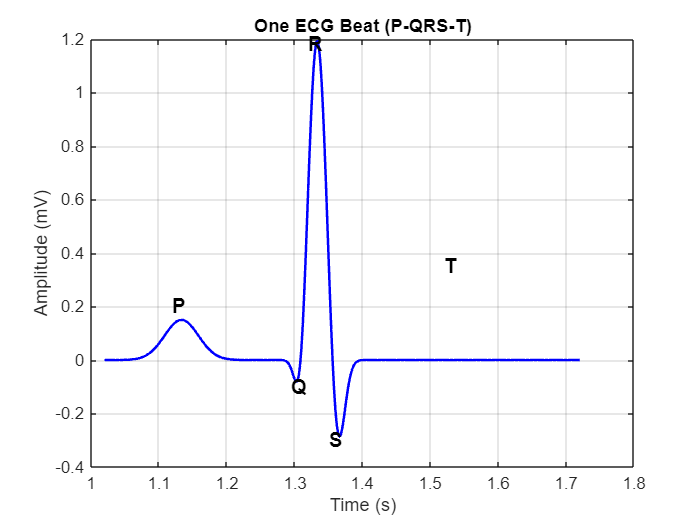

%% Part 6: Zoom into one beat to inspect P-QRS-T 
beatStart = rPeaks(2) - round(0.3*fs); 
beatEnd   = rPeaks(2) + round(0.4*fs); 
figure('Name','Single Beat Morphology'); 
plot(t(beatStart:beatEnd), ecgClean(beatStart:beatEnd), 'b', 'LineWidth', 1.5); 
xlabel('Time (s)'); ylabel('Amplitude (mV)'); 
title('One ECG Beat (P-QRS-T)'); 
grid on; 
% Annotate waves 
text(t(rPeaks(2)-round(0.20*fs)), 0.20, 'P', 'FontSize',12,'FontWeight','bold'); 
text(t(rPeaks(2)-round(0.025*fs)), -0.10, 'Q', 'FontSize',12,'FontWeight','bold'); 
text(t(rPeaks(2)), 1.18, 'R', 'FontSize',12,'FontWeight','bold'); 
text(t(rPeaks(2)+round(0.030*fs)), -0.30, 'S', 'FontSize',12,'FontWeight','bold'); 
text(t(rPeaks(2)+round(0.20*fs)), 0.35, 'T', 'FontSize',12,'FontWeight','bold');

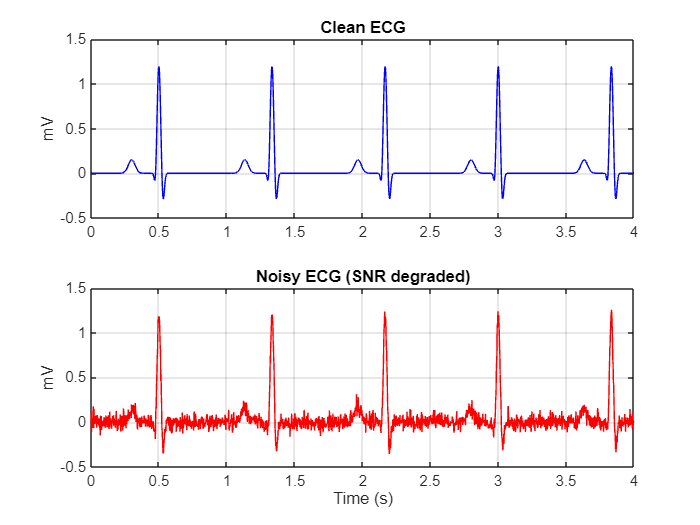

%% Part 7: Add noise and see time domain degradation 
noiseLevel = 0.05;                          
% mV 
ecgNoisy = ecgClean + noiseLevel * randn(size(t)); 
figure('Name','Clean vs Noisy ECG'); 
subplot(2,1,1); 
plot(t, ecgClean, 'b'); xlim([0 4]); grid on; 
title('Clean ECG'); ylabel('mV'); 
subplot(2,1,2); 
plot(t, ecgNoisy, 'r'); xlim([0 4]); grid on; 
title('Noisy ECG (SNR degraded)'); xlabel('Time (s)'); ylabel('mV'); 

%% Part 8: SNR calculation 
signalPower = mean(ecgClean.^2); 
noisePower  = mean((ecgNoisy - ecgClean).^2); 
snr_dB = 10 * log10(signalPower / noisePower); 
fprintf('SNR of noisy ECG: %.2f dB\n', snr_dB); 

SNR of noisy ECG: 11.93 dB
